# Data Exploration

**Loading Data**

addpath('Subcodes');
addpath('DATA');
close all;
load('DATASTRUCT');
numRow = length(DATA.country_destination);% Number of data rows

**Dividing data into training and testing:**

testRatio = 0.2; % Portion of data associated for testing
numTest = floor(testRatio*numRow);
numTrain = numRow-numTest;
testIndex = [true(numTest,1);false(numTrain,1)];
randInex= randperm(numRow);
testIndex = testIndex(randInex);
[~,sortIndex]=sort(DATA.timestamp_first_active,'ascend');
testDATA = DATA;
trainDATA = DATA;
fieldNames = fieldnames(DATA);
for i = 1:length(fieldNames)
    temp = DATA.(fieldNames{i})(sortIndex);
    DATA.(fieldNames{i}) = temp;
    testDATA.(fieldNames{i}) = temp(testIndex);
    trainDATA.(fieldNames{i}) = temp(~testIndex);
end

**Finding the percentage of missing entities:**

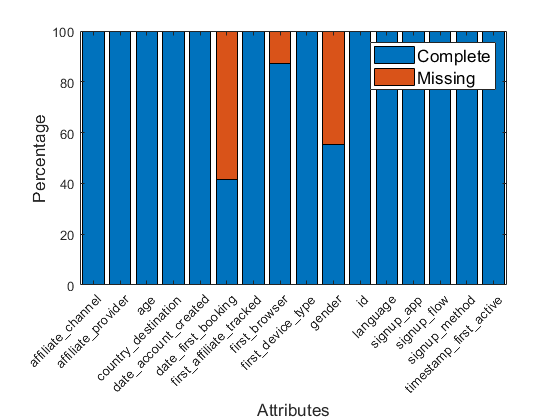

missDataPlot(trainDATA,fieldNames,axisNames);

## Univariate Analysis

**Destination Country:**

We can see 58% of the users did not book through Airbnb. 29% Percent of the users choose US as their first destination.

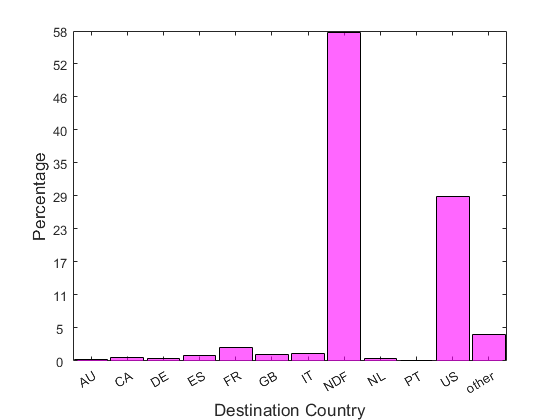

catPercents(trainDATA.country_destination,[1,0,1],'Destination Country',...
    'Percentage');

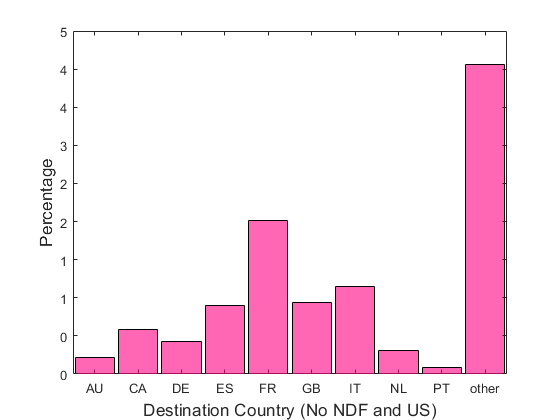

catPercents(removecats(trainDATA.country_destination,{'NDF','US'}),[1,0,0.5],'Destination Country (No NDF and US)',...
    'Percentage');

**Gender:**

While almost 45% of the users did not insert their gender, percentage of female users is higher than the male users.

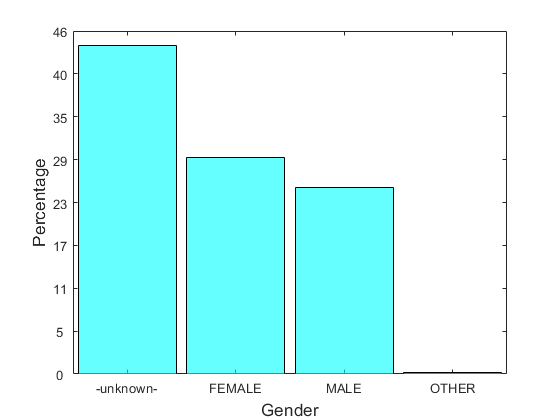

catPercents(trainDATA.gender,[0,1,1],'Gender', 'Percentage');

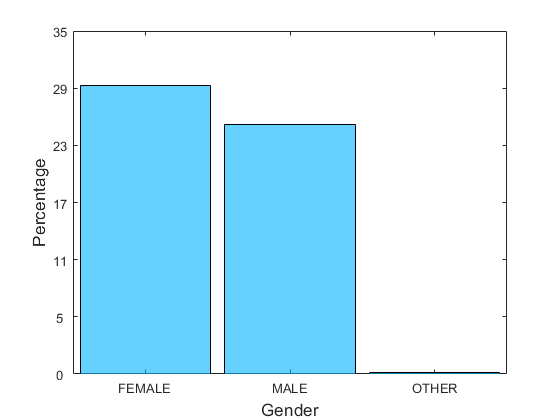

catPercents(removecats(trainDATA.gender,'-unknown-'),[0,0.7,1],'Gender', 'Percentage');

**First Device Type:**

Desktop devices have the highest percentage of usage between the users.

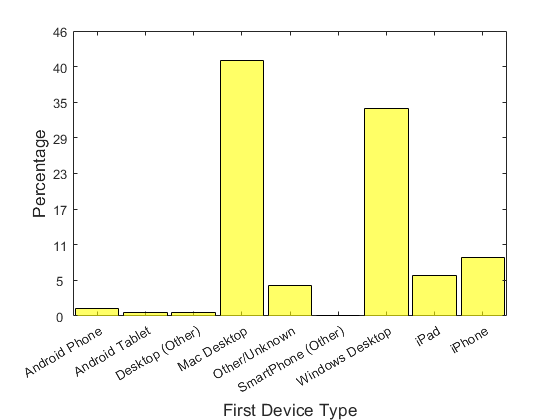

catPercents(trainDATA.first_device_type,[1,1,0],'First Device Type',...
    'Percentage');

**Age:**

At the first glance, we can observe that some of the age entries are not acceptable. Thus, we limit our age entries between 18 and 100. We can see that the users between the age of 25-40 tend to use Airbnb more than the other users. 

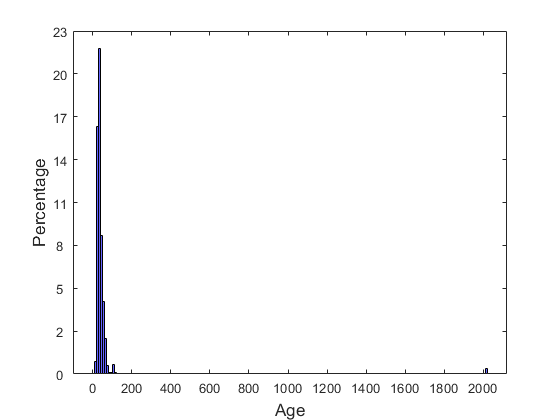

catPercents(trainDATA.age,[0,0,1],'Age', 'Percentage');

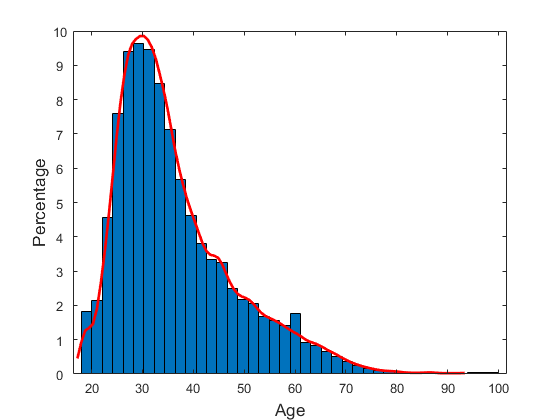

trainDATA = dataCleaner(trainDATA,fieldNames,(trainDATA.age>100 | ...
    trainDATA.age<18));
numPercents(trainDATA.age,'Age', 'Percentage');

Timestamp_first_active conversion to datetime:

trainDATA.date_first_active = datetime(num2str(floor(...
    trainDATA.timestamp_first_active/1000000)),'InputFormat','yyyyMMdd');

Extracting weekday, month and year from the date_account created:

[~,trainDATA.date_account_created_day]=weekday(...
    trainDATA.date_account_created);
trainDATA.date_account_created_day = categorical(cellstr(...
    trainDATA.date_account_created_day));
trainDATA.date_account_created_month_str=categorical(cellstr(month(...
    trainDATA.date_account_created,'name')));
trainDATA.date_account_created_month_number=month(...
    trainDATA.date_account_created);
trainDATA.date_account_created_year=year(...
    trainDATA.date_account_created);

**Weekday:**

We can see that the users are less active on weekends

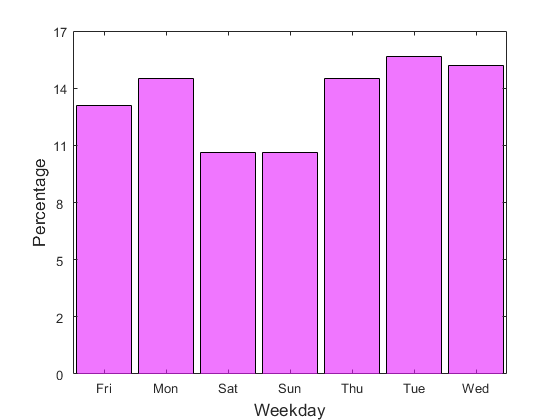

catPercents(trainDATA.date_account_created_day,[0.9,0.1,1],'Weekday',...
    'Percentage');

**Language:**

User's highest language preference is English.

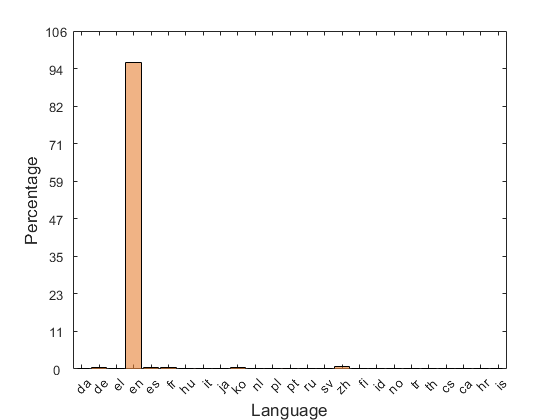

catPercents(trainDATA.language,[0.9,0.5,0.2],'Language','Percentage');

**Affiliate provider:**

Most of the users used Airbnb website directly to signup while Google was the second affiliate provider. 

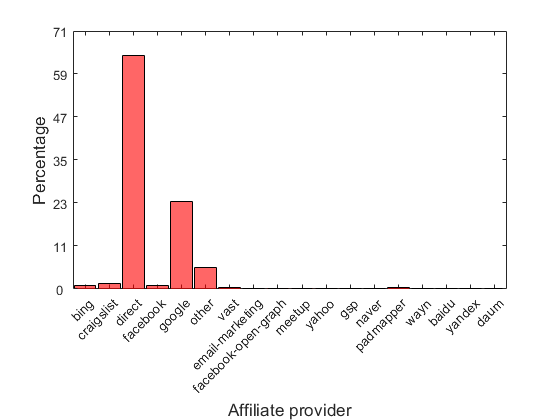

catPercents(trainDATA.affiliate_provider,[1,0,0],'Affiliate provider',...
    'Percentage');

**Account creating date:**

We can see an increase in the number of account creations during timewhich shows the increase in the reputation of Airbnb.

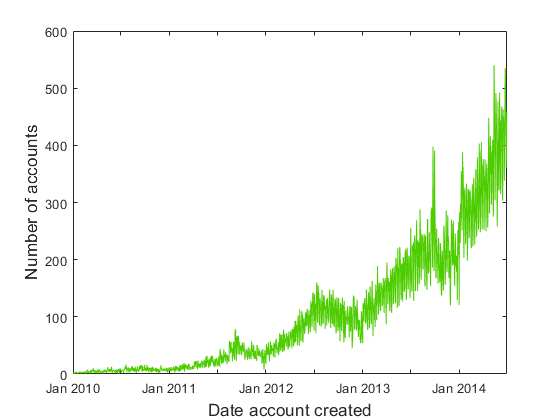

datePlot(trainDATA.date_account_created,'Date account created','Number of accounts',[0.3,0.8,0]);

## Bivariate Analysis:

**Account creation month and year:**

We can see that the account creation pattern is very similar every year.

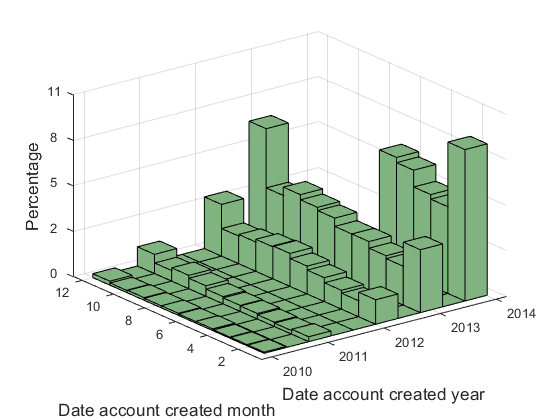

catBiPercents(trainDATA.date_account_created_year,...
    trainDATA.date_account_created_month_number,[0.5,0.7,0.5],...
    'Date account created year','Date account created month','Percentage');

**Country Destintation VS signup app:**

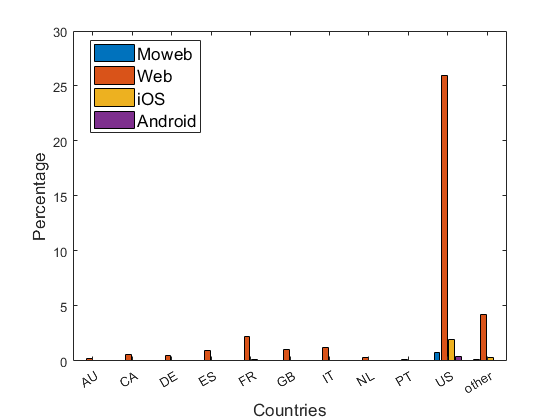

biVarBar(removecats(trainDATA.country_destination,'NDF'),...
    trainDATA.signup_app,'Countries','Percentage');

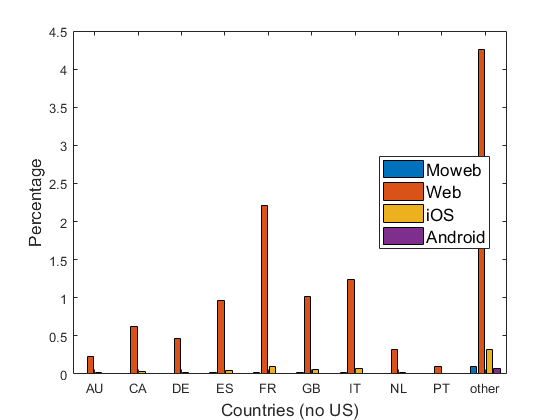

biVarBar(removecats(trainDATA.country_destination,{'NDF','US'}),...
    trainDATA.signup_app,'Countries (no US)','Percentage');

**Country Destintation VS signup method:**

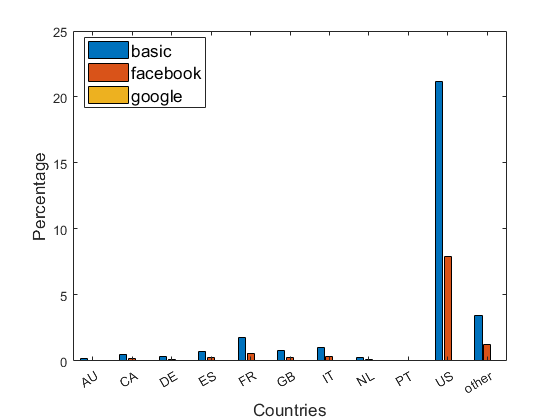

biVarBar(removecats(trainDATA.country_destination,'NDF'),...
    trainDATA.signup_method,'Countries','Percentage');

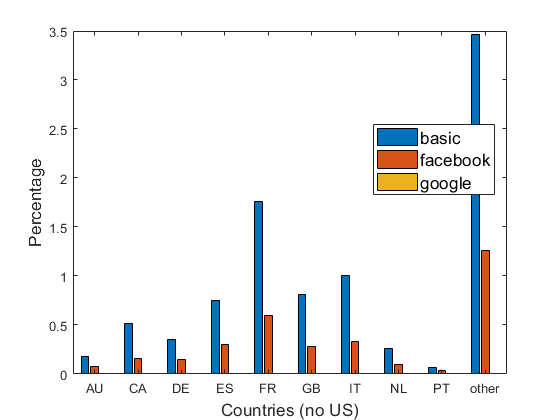

biVarBar(removecats(trainDATA.country_destination,{'NDF','US'}),...
    trainDATA.signup_method,'Countries (no US)','Percentage');

**Country Destintation VS Age:**

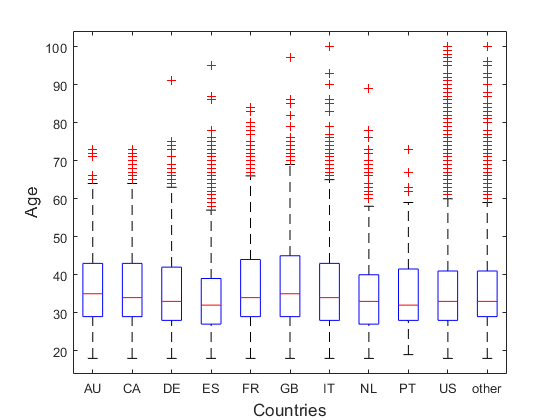

biVarBoxPlot(trainDATA.age,removecats(trainDATA.country_destination,...
    'NDF'),'Countries','Age');